% Andrew Hutsell
% MATH 515
% Problem Set 4

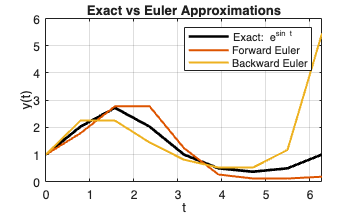

% Problem 4

% Part e
% Step size and grid
h = pi/4;
t = 0:h:2*pi;
N = length(t);

% Exact solution
y_exact = exp(sin(t));

% Forward Euler
y_fe = zeros(1,N);
y_fe(1) = 1;

for n = 1:N-1
    y_fe(n+1) = y_fe(n) + h * y_fe(n) * cos(t(n));
end

% Backward Euler
y_be = zeros(1,N);
y_be(1) = 1;

for n = 1:N-1
    y_be(n+1) = y_be(n) / (1 - h*cos(t(n+1)));
end

% Plot
figure;
plot(t, y_exact, 'k-', 'LineWidth', 2); hold on;
plot(t, y_fe, 'LineWidth', 1.5);
plot(t, y_be, 'LineWidth', 1.5);
legend('Exact: e^{sin t}', 'Forward Euler', 'Backward Euler');
xlabel('t'); ylabel('y(t)');
title('Exact vs Euler Approximations');
grid on;


% Error for Forward Euler
error_fe = max(abs(y_exact - y_fe))

error_fe = 0.8167


% Theoretical bound
bound = h * exp(pi) * (exp(2*pi) - 1)

bound = 9.7142e+03

clear; clc; close all;
% Problem 5

f = @(t,y) sin(t) + y;
h = 0.5;
t = 0;
y_feuler = 0;

% Part b
% Forward Euler

for n = 1:2
    y_feuler = y_feuler + h*f(t,y_feuler);
    t = t + h;
end

y_exact = 0.5*(exp(1) - sin(1) - cos(1));

error_5a = abs(y_exact - y_feuler);

disp(y_feuler)

    0.2397



disp(y_exact)

    0.6683



disp(error_5a)

    0.4285



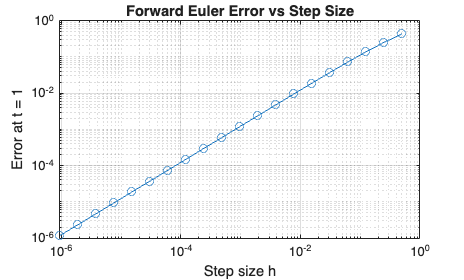



% Part c
tic;
Nh_values = 2.^(1:20);
errors_5c = zeros(size(Nh_values));
h_values = 1 ./ Nh_values;

y_exact = 0.5*(exp(1) - sin(1) - cos(1));

for k = 1:length(Nh_values)
    Nh = Nh_values(k);
    h = 1/Nh;
    
    t = 0;
    y = 0;
    
    for n = 1:Nh
        y = y + h * f(t,y);
        t = t + h;
    end
    
    errors_5c(k) = abs(y_exact - y);
end
figure();
loglog(h_values, errors_5c, '-o')
xlabel('Step size h')
ylabel('Error at t = 1')
title('Forward Euler Error vs Step Size')
grid on

time_feuler = toc

time_feuler = 0.0992


% Part d and e

tic;
Nh = 2;
h = 1/Nh;
t = 0;
y_beuler = 0;

for n = 1:Nh
    t_next = t + h;
    y_beuler = (y_beuler + h*sin(t_next)) / (1 - h);
    t = t_next;
end

y_beuler = y;

y_exact = 0.5*(exp(1) - sin(1) - cos(1));
error_5d = abs(y_exact - y_beuler);

disp(y_beuler)

    0.6683



disp(error_5d)

   1.1674e-06



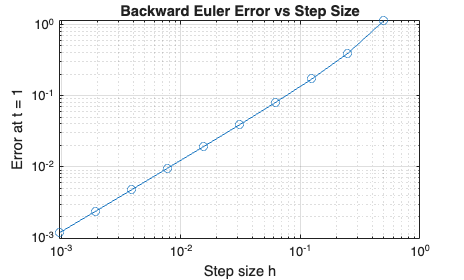


Nh_values = 2.^(1:10);
errors_5d_2 = zeros(size(Nh_values));
h_values = 1 ./ Nh_values;

y_exact = 0.5*(exp(1) - sin(1) - cos(1));

for k = 1:length(Nh_values)
    Nh = Nh_values(k);
    h = 1/Nh;
    
    t = 0;
    y_beuler = 0;
    
    for n = 1:Nh
        t_next = t + h;
        y_beuler = (y_beuler + h*sin(t_next)) / (1 - h);
        t = t_next;
    end
    
    errors_5d_2(k) = abs(y_exact - y_beuler);
end
figure();
loglog(h_values, errors_5d_2, '-o')
xlabel('Step size h')
ylabel('Error at t = 1')
title('Backward Euler Error vs Step Size')
grid on

time_beuler = toc

time_beuler = 0.0302